In this script, we are going to solve the problem of a **semi-infinite wedge**. We assume a stress function, $\phi$  which can be used to derive the stresses- $\sigma_r ,\sigma_{\theta \;} \;\textrm{and}\;\sigma_{r\theta }$.

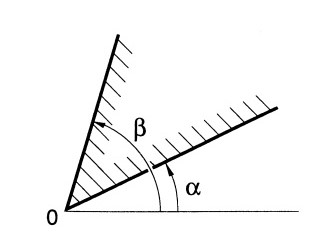

clc; clear all; close all;
syms r theta;
syms n;
syms f(theta);
syms A1 A2 A3 A4;
n_value = 0;

We first consider the case where traction on the boundary varies as $r^n$. So our stress function has to be of the form $\phi =r^{n+2} f\left(\theta \right)$.

phi = r^(n+2)*f(theta);

However for this case we set $n=0$. Thus  $\phi =r^2 f\left(\theta \right)$.

phi = subs(phi,n,n_value);

Substituting in the Laplacian operator$\nabla^2 \phi$, we get-

disp(polarLaplacian(phi))

$$\frac{\partial^{2}}{\partial \theta^{2}}f\left(\theta \right)+4\,f\left(\theta \right)$$

Substituting in the biharmonic equation $\nabla^4 \phi$, we get-

disp(polarBiharmonic(phi))

$$\frac{\frac{\partial^{4}}{\partial \theta^{4}}f\left(\theta \right)+4\,\frac{\partial^{2}}{\partial \theta^{2}}f\left(\theta \right)}{r^{2}}$$

Solving the biharmonic equation $\nabla^4 \phi =0$

eq = subs(polarBiharmonic(phi),n,n_value) ==0

$$eq = \frac{\frac{\partial^{4}}{\partial \theta^{4}}f\left(\theta \right)+4\,\frac{\partial^{2}}{\partial \theta^{2}}f\left(\theta \right)}{r^{2}}=0$$

f_ob(theta) = simplify(dsolve(subs(eq*r^(n+2),n,n_value)));

phi_ob = simplify(r^(2)*f_ob(theta));
matlabConst = setdiff(symvar(phi_ob),[r,theta,n]);
phi_ob = subs(phi_ob, matlabConst, [A4,A3,A1,A2]);

Thus, the new stress function obtained, $\phi_{\textrm{ob}}$ is-

phi_ob = subs(phi_ob,A4/4,A4);
phi_ob = subs(phi_ob,-A2,A2);
phi_ob = rewrite(phi_ob,'sincos')

$$phi\_ob = r^{2}\,\left(A_{3}+A_{4}\,\theta +A_{1}\,\cos\left(2\,\theta \right)+A_{2}\,\sin\left(2\,\theta \right)\right)$$

We can find the stress components $\sigma_r ,\sigma_{\theta \;} \;\textrm{and}\;\sigma_{r\theta }$ from the Stress Function, $\phi_{\textrm{ob}}$.

stress = polarStressMatrix(phi_ob);
sigma_r = stress(1,1)

$$sigma\_r = 2\,A_{3}+2\,A_{4}\,\theta -2\,A_{1}\,\cos\left(2\,\theta \right)-2\,A_{2}\,\sin\left(2\,\theta \right)$$

sigma_t = stress(2,2)

$$sigma\_t = 2\,A_{3}+2\,A_{4}\,\theta +2\,A_{1}\,\cos\left(2\,\theta \right)+2\,A_{2}\,\sin\left(2\,\theta \right)$$

sigma_rt = stress(1,2)

$$sigma\_rt = 2\,A_{1}\,\sin\left(2\,\theta \right)-2\,A_{2}\,\cos\left(2\,\theta \right)-A_{4}$$